% This m-file shows how to  generate  a reduced order model.

format short e

% NOTE -- this is NOT the transfer function of the magnetic suspended ball
% Replace with right A,B,C,D

num = .1;
den = conv([1 1],[.1 1])

den =    1.0000e-01   1.1000e+00   1.0000e+00



[A,B,C,D] = tf2ss(num,den);
G = ss(A,B,C,D);

% eigenvalues and zeros of full order model
plant_eigenvalues =  eig(A)

plant_eigenvalues =    -10
    -1


plant_zeros =   tzero(A,B,C,D)


plant_zeros =

  0×1 empty double column vector




% find the reduced order model by using modal residualization
% note that you 
 
[am,bm,cm,dm] = canon(A,B,C,D,'modal');  % diagonalizes system
 
am

am =    -10     0
     0    -1



% elim = input('which states to delete?     '); % enter which state you wish to delete
elim = 2

elim =      2


[ar,br,cr,dr] = modred(am,bm,cm,dm,elim);
Gr = ss(ar,br,cr,dr);

% eigenvalues and zeros of reduced order model
reduced_mod_evalues = eig(ar)

reduced_mod_evalues =    -10


reduced_mod_zeros = tzero(ar,br,cr,dr)

reduced_mod_zeros =     -9



% compare Bode plots
figure(1)
clf

## Bode Comparison

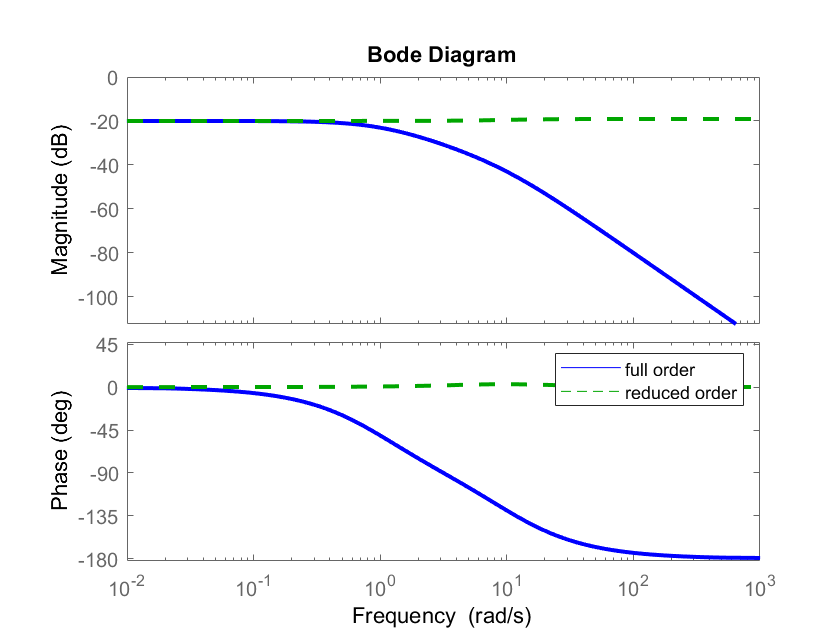

%% note that using the PhaseWrapping option will
% insure that phase angles are plotted using their principal values
% and thus that a phase angle of 0 is not plotted as 360.
h=bodeplot(G,'b-',Gr,'g--');
p = getoptions(h); 
p.PhaseWrapping = 'on'; 
setoptions(h,p); % Update the Bode plot.
legend('full order','reduced order')
set(findall(gcf,'type','line'),'linewidth',2)